# DDMR Kinematics

[https://www.semanticscholar.org/paper/Controllers-design-for-differential-drive-mobile-on-Contreras-Herrera/02e4ee7a2c7df20833e24977e4fb2eb052186726](https://www.semanticscholar.org/paper/Controllers-design-for-differential-drive-mobile-on-Contreras-Herrera/02e4ee7a2c7df20833e24977e4fb2eb052186726)

[https://www.youtube.com/watch?v=YxuJFQZh94Q](https://www.youtube.com/watch?v=YxuJFQZh94Q)

[https://www.youtube.com/watch?v=RZlZcDxQ8P4](https://www.youtube.com/watch?v=RZlZcDxQ8P4) 

[https://www.scribd.com/document/707050213/DDMR-TRAJECTORY-TRACKING-WITH-USING-PID-AND-KINEMATIC-BASED-BACKSTEPPING-CONTROLLER](https://www.scribd.com/document/707050213/DDMR-TRAJECTORY-TRACKING-WITH-USING-PID-AND-KINEMATIC-BASED-BACKSTEPPING-CONTROLLER) 

[https://arxiv.org/pdf/2202.12391.pdf](https://arxiv.org/pdf/2202.12391.pdf)

[https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9324733/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9324733/)

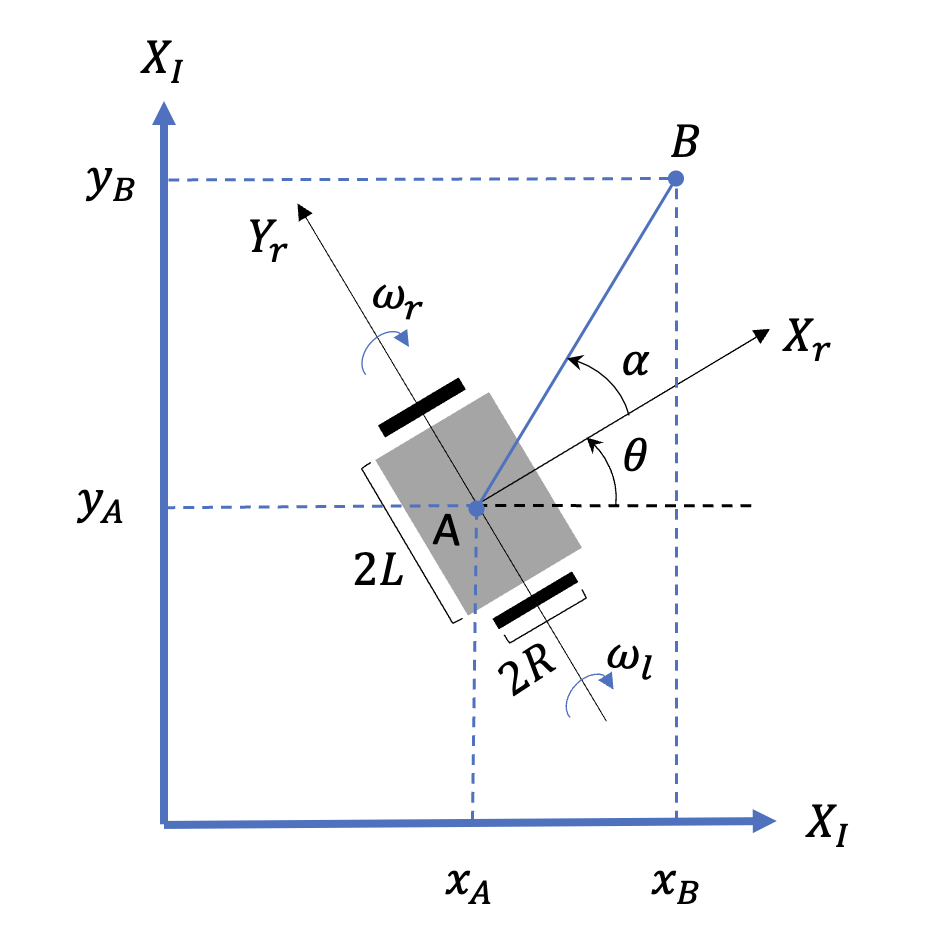

$\left\lbrace X_{I\;} ,Y_I \right\rbrace$ Inerial Frame

$\left\lbrace X_r \;,Y_r \right\rbrace$ Inerial Frame

$\omega_r \left(t\right)$ Right Wheel angular speed             [rad/s]

$\omega_l \left(t\right)$ Left Wheel angualr speed                [rad/s]

$v_A \left(t\right)$ Body linear velocity                          [m/s]

$\omega_A \left(t\right)$ Body angular velocity                      [rad/s]

$\theta$ Robot heading angle                             [rad]

$x_A$ Body x position in Interial Frame 

$y_A$ Body y position in Intertial Frame

## Inverse Kinematics


$$\left\lbrack \begin{array}{c}
\omega_r \\
\omega_l 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
v_a -Lw_a \\
v_a +Lw_a 
\end{array}\right\rbrack$$


  
$${\omega_r =\;v}_A -\omega_A L$$



$$\omega_l =v_A +\omega_A L$$



$$v_A =\frac{R\left(\omega_R +\omega_L \right)\;}{2}$$



$$\omega_A =\frac{R\left(\omega_R -\omega_L \right)\;}{2L}\;$$


### Forward Kinematics 

Inertial Frame


$${\dot{q} }_A^I =\left\lbrack \begin{array}{c}
{\dot{x} }_A^I \\
{\dot{y} }_A^I \\
{\dot{\theta} }_A^I 
\end{array}\right\rbrack =\frac{R}{2}\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & \cos \left(\theta \right)\\
\sin \left(\theta \right) & \sin \left(\theta \right)\\
\frac{1}{L} & -\frac{1}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\omega_r \\
\omega_l 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & 0\\
\sin \left(\theta \right) & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_a \\
\omega_a 
\end{array}\right\rbrack$$
 

Robot Frame

Restricting $v_A ={\dot{x} }_P^R \ge 0$, this is reasonobale as in the race the buggy will only have to drive forwards.


$${\dot{q} }_A^R =\left\lbrack \begin{array}{c}
{\dot{x} }_A^R \\
{\dot{y} }_A^R \\
{\dot{\theta} }_A^R 
\end{array}\right\rbrack =\frac{R}{2}\left\lbrack \begin{array}{cc}
1 & 1\\
0 & 0\\
\frac{1}{L} & \frac{1}{L}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_A -\omega_A L\\
v_A +\omega_A L
\end{array}\right\rbrack \;\;$$


Sensor Array outputs $y_p^R =\frac{\sum_{i=5} G_i {\textrm{Vsense}}_i \;}{5}$ 


$$
    \ G_i\ = \left\{\begin{array}{lr}
        -100, & \text{for } i = 0\\
        -50, & \text{for } i = 1\\
        1, & \text{for } i =2 \\
        50, & \text{for } i = 3 \\
        100, & \text{for } i = 4

        \end{array}
  \$$



$$\left|{\dot{x} }_P^R \right|=\left|{\dot{x} }_A^R \right|=\left|v_A \right|\;\;$$



$$\omega_A =\dot{\alpha \;} =\tan^{-1} \left(\frac{{\dot{y} }_P^R \;}{{\dot{x} }_P^R \;}\right)$$


% Model Parameters
L = 0.075;     % Wheel Base 
R = 0.035;    % Wheel Radius m
gR = 20;
% Model